% Step 1: Preprocessing
imageFile = 'barbara256.png';
originalImg = imread(imageFile);

Error using imread>get_full_filename (line 579)
Unable to find file "barbara256.png".

Error in imread (line 372)
        fullname = get_full_filename(filename);

if size(originalImg, 3) == 3
    originalImg = rgb2gray(originalImg); % Convert to grayscale if RGB
end
originalImg = double(originalImg); % Convert to double for processing
[rows, cols] = size(originalImg);

% Display the original image
figure; imshow(uint8(originalImg)); title('Original Image');

function diffused_image = homo_diffusion(sparse_image, mask, num_iterations, lambda)
    % Performs diffusion (Homogeneous or Biharmonic) on a sparse image.
    %
    % Inputs:
    %   - sparse_image: Sparse grayscale image with known values
    %   - mask: Binary mask indicating known values (1 = known, 0 = unknown)
    %   - num_iterations: Number of diffusion iterations
    %   - method: Diffusion method ('homogeneous' or 'biharmonic')
    %   - lambda: Diffusion rate (time step, e.g., 0.1)
    %
    % Outputs:
    %   - diffused_image: Processed image after diffusion
    
    % Initialize the image with the sparse input
    diffused_image = sparse_image;
    
    % Define Laplacian operator (second-order derivatives)
    laplacian_kernel = [0  1  0;
                        1 -4  1;
                        0  1  0];
    
    kernel = laplacian_kernel;

    % Perform iterative diffusion
    for t = 1:num_iterations
        % Compute the diffusion update
        diffused_update = imfilter(diffused_image, kernel, 'symmetric');
        
        % Update the image
        diffused_image = diffused_image + lambda * diffused_update;
        
        % Ensure sparse values remain unchanged
        diffused_image(mask == 1) = sparse_image(mask == 1);
    end
end

% Create sparse image and mask
mask = rand(size(original_image)) > 0.9;% 10% random pixels
sparse_image = zeros(size(original_image));
sparse_image(mask) = original_image(mask);

% Parameters
num_iterations = 100;  % Number of iterations
lambda = 0.1;          % Diffusion rate

% Perform Homogeneous Diffusion
homogeneous_image = homo_diffusion(sparse_image, mask, num_iterations,lambda);
mseError = mean((homogeneous_image(:) - originalImg(:)).^2)

mseError = 693.9663

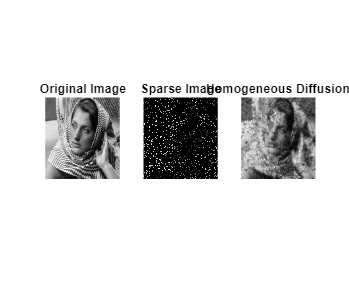


% Display results
figure;
subplot(1, 3, 1); imshow(original_image, []); title('Original Image');
subplot(1, 3, 2); imshow(uint8(sparse_image), []); title('Sparse Image');
subplot(1, 3, 3); imshow(homogeneous_image, []); title('Homogeneous Diffusion');

global sparseImg;
% Recursive Subdivision with Binary Tree Encoding and Pixel Locations
function [binaryTree] = subDivide(img, region, threshold, maxDepth, depth, binaryTree)
    % img           : Original image
    % region        : [startRow, startCol, endRow, endCol] of the current region
    % threshold     : Error threshold
    % maxDepth      : Maximum recursion depth
    % depth         : Current recursion depth
    % binaryTree    : Encodes the binary tree structure
    % vertexValues  : Stores pixel values of selected vertices
    % pixelLocations: Stores pixel coordinates of selected vertices
    
    global sparseImg;
    % Extract region boundaries
    startRow = region(1); startCol = region(2);
    endRow = region(3); endCol = region(4);

    % Compute midpoints for splitting
    midRow = floor((startRow + endRow) / 2);
    midCol = floor((startCol + endCol) / 2);

    % Extract the region of interest
    subImg = img(startRow:endRow, startCol:endCol);
    [h, w] = size(subImg);

    if depth == 0
        sparseImg = zeros(size(subImg));
    end

    % 0: Use diffusion to reconstruct the rectangle to be subdivided
    borderPoints = [startRow, startCol; startRow, midCol; startRow, endCol;
                    midRow, startCol;  midRow, midCol; midRow, endCol;
                    endRow, startCol; endRow, midCol; endRow, endCol];

    % Place the intensity values of the selected points
    for i = 1:size(borderPoints, 1)
        row = borderPoints(i, 1); % Row coordinate of the point
        col = borderPoints(i, 2); % Column coordinate of the point

        %{
        if depth == 0
            sparseImg(row, col) = img(row, col);
        elseif ~(row == startRow || row == endRow || col == startCol || col == endCol)
            sparseImg(row, col) = img(row, col); % Copy intensity value
        end
        %}
        sparseImg(row, col) = img(row, col);
    end
    
    subSparseImg = sparseImg(startRow:endRow, startCol:endCol);
    mask = subSparseImg > 0.5;

    % Reconstruction Error
    lambda = 20;
    num_iterations = 10;

    %diffusedImg = EED(sparseImg, region, borderPoints, lambda, sigma, numIterations);
    homogeneous_image = homo_diffusion(subSparseImg, mask, num_iterations, lambda);

    mseError = mean((homogeneous_image(:) - subImg(:)).^2);

    % Check stopping condition
    if mseError <= threshold || depth >= maxDepth
        % Add a leaf node (0) to the binary tree
        binaryTree = [binaryTree, 0]; 
        return;
    end
    % Add an internal node (1) to the binary tree
    binaryTree = [binaryTree, 1];

    % Define sub-regions
    if h > w
        subRegions = {
            [startRow, startCol, midRow, endCol], 
            [midRow, startCol, endRow, endCol], 
         };
    else
        subRegions = {
            [startRow, startCol, endRow, midCol], 
            [startRow, midCol, endRow, endCol] 
        };
    end

    % Recursively process each sub-region
    for i = 1:2
        [binaryTree] = subDivide(img, subRegions{i}, threshold, maxDepth, depth + 1, binaryTree);
    end
end


% Example usage of recursive subdivision with binary tree, vertex values, and pixel locations
threshold = 20; % Error threshold for stopping
maxDepth = 3;   % Maximum recursion depth
initialRegion = [1, 1, size(originalImg, 1), size(originalImg, 2)]; % Entire image region

Unrecognized function or variable 'originalImg'.

[binaryTree] = subDivide(originalImg, initialRegion, threshold, maxDepth, 0, []);


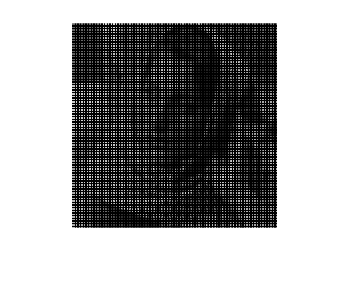

% Function to display non-zero points in a sparse image
function displayNonZeroPoints(sparseImg)
    % Input:
    % sparseImg : Sparse image with non-zero values at specific locations
    
    % Find the non-zero points
    [rows, cols] = find(sparseImg > 0); % Rows and columns of non-zero points
    
    % Display the sparse image
    figure; imshow(uint8(sparseImg)); hold on;
    
    % Overlay the non-zero points with red markers
    plot(cols, rows, 'r.', 'MarkerSize', 10); % Plot markers at (col, row)
    title('Non-Zero Points in Sparse Image');
    
    % Display the number of non-zero points
    fprintf('Number of non-zero points: %d\n', numel(rows));
end

% Example usage
%displayNonZeroPoints(sparseImg);
figure;imshow(uint8(sparseImg));

% Function to extract locations and vertex values from a sparse image
function [locations, vertexValues] = extractSparseImageInfo(sparseImg)
    % Input:
    % sparseImg : Sparse image with non-zero values representing vertices
    
    % Find non-zero points and their values
    [rows, cols] = find(sparseImg); % Rows, columns, and intensities of non-zero elements
    
    % Combine row and column indices into locations
    locations = [rows, cols]; % Nx2 array of coordinates (row, col)
    locations = sortrows(unique(locations, 'rows'));

    % Store the non-zero intensities
    linear_indices = sub2ind(size(sparseImg), locations(:, 1), locations(:, 2));
    vertexValues = sparseImg(linear_indices); % Nx1 array of intensities
    
    % Display results
    fprintf('Extracted %d locations and vertex values from the sparse image.\n', size(linear_indices));
end

% Example usage
[locations, vertexValues] = extractSparseImageInfo(sparseImg);

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.


fprintf('Size of Binary Tree: %d bits\n', numel(binaryTree));

Size of Binary Tree: 8191 bits


global BCT
BCT = binaryTree;

% Helper Function to Extract All Locations
function locations = extractLocations(region, depth)
    global BCT;
    locations = [];
    % Extract current bit and pop it from the binaryTree
    currentBit = BCT(1);
    BCT(1) = []; % Remove the first bit

    % Extract region boundaries
    startRow = region(1); startCol = region(2);
    endRow = region(3); endCol = region(4);

    % Compute midpoints for splitting
    midRow = floor((startRow + endRow) / 2);
    midCol = floor((startCol + endCol) / 2);

    % Extract the region of interest
    h = endRow - startRow;
    w = endCol - startCol;

    % define border points
    borderPoints = [startRow, startCol; startRow, midCol; startRow, endCol;
                    midRow, startCol;  midRow, midCol; midRow, endCol;
                    endRow, startCol; endRow, midCol; endRow, endCol];

    % Place the intensity values of the selected points
    for i = 1:size(borderPoints, 1)
        row = borderPoints(i, 1); % Row coordinate of the point
        col = borderPoints(i, 2); % Column coordinate of the point
        %{
        if depth == 0
            locations = [locations; row, col]; % 1st boundary
        elseif ~(row == startRow || row == endRow || col == startCol || col == endCol)
            locations = [locations; row, col]; % get points
        end
        %}
        locations = [locations; row, col];

    end

    % Check stopping condition
    if currentBit == 0
        return;
    end

    % Define sub-regions
    if h > w
        subRegions = {[startRow, startCol, midRow, endCol], [midRow, startCol, endRow, endCol], };
    else
        subRegions = { [startRow, startCol, endRow, midCol], [startRow, midCol, endRow, endCol] };
    end

    % Recursively process each sub-region
    for i = 1:2
         locations = [locations; extractLocations(subRegions{i}, depth+1)];
    end
end

initial_region = [1, 1, size(originalImg, 1), size(originalImg, 2)]

initial_region =      1     1   256   256


decodedLocations = extractLocations(initial_region, 0);
decodedLocations = sortrows(unique(decodedLocations, 'rows'));
if (decodedLocations == sortrows(unique(locations, 'rows')))
    fprintf("Decoder locations successful");
else
    fprintf("Decoder locations not successful");
end

Decoder locations successful

BCT = binaryTree;
% Decoder Function
function [sparseImg, sortedLocations] = decoder(region, intensityValues)
    % Input:
    % imageDims      : Dimensions of the sparse image
    % sortedLocations: Sorted locations of non-zero points
    % intensityValues: Corresponding intensities of the locations

    % Initialize the sparse image
    endRow = region(3);
    endCol = region(4);
    sparseImg = zeros(endRow, endCol);

    % Extract all locations
    locations = extractLocations(region, 0);
    locations = unique(locations,'rows');

    % Sort locations lexicographically (row first, then column)
    sortedLocations = sortrows(locations);

    % Assign intensity values to the corresponding locations
    for i = 1:size(sortedLocations, 1)
        row = sortedLocations(i, 1);
        col = sortedLocations(i, 2);
        try
            sparseImg(row, col) = intensityValues(i);
        catch
            disp(i);
            disp(size(locations));
        end
    end
end

[decodedImage, decodedLocations] = decoder(initial_region, vertexValues);

if (decodedImage == sparseImg)
    fprintf("Decoder successful");
else
    fprintf("Decoder not successful");
end

Decoder successful

figure; imshow(uint8(decodedImage));

% Parameters
num_iterations = 100;  % Number of iterations
lambda = 0.1; % Diffusion rate
mask = decodedImage > 0.1;

% Perform Homogeneous Diffusion
reconsImage = homo_diffusion(decodedImage, mask, num_iterations,lambda);
mseError = mean((reconsImage(:) - originalImg(:)).^2)

mseError = 170.5460

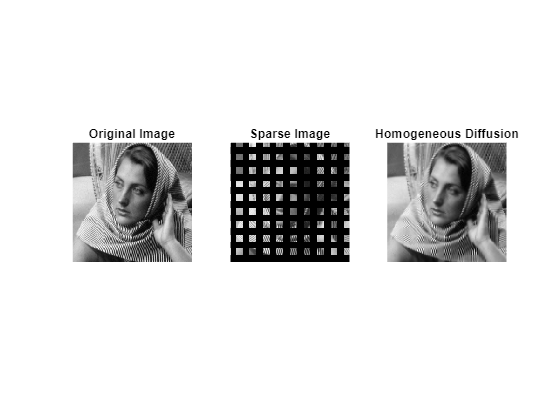


% Display results
figure;
subplot(1, 3, 1); imshow(original_image, []); title('Original Image');
subplot(1, 3, 2); imshow(uint8(decodedImage), []); title('Sparse Image');
subplot(1, 3, 3); imshow(reconsImage, []); title('Homogeneous Diffusion');

%binaryTree and intensityValues

function [encoded_data, dict] = huffman_compress(input_array)
    % Compress an array using Huffman encoding
    %
    % Inputs:
    %   - input_array: Array of integers or symbols to be compressed
    %
    % Outputs:
    %   - encoded_data: Compressed binary data (cell array of bits)
    %   - dict: Huffman dictionary for decoding
    
    % Flatten the input array and calculate symbol frequency
    symbols = unique(input_array(:));
    freq = histc(input_array(:), symbols);
    
    % Generate Huffman dictionary
    dict = huffmandict(symbols, freq / sum(freq));
    
    % Encode the input array
    encoded_data = huffmanenco(input_array(:), dict);
end

% Compress using Huffman encoding
[encoded_data, dict] = huffman_compress(vertexValues);

% Display results
disp('Huffman Dictionary:');

Huffman Dictionary:


disp(dict);

    {[ 24]}    {[1 1 0 0 0 0 1 1 0 0 0 0 1 1]}
    {[ 25]}    {[  1 1 0 0 0 0 1 1 0 0 0 0 0]}
    {[ 26]}    {[      0 0 1 0 0 0 1 0 0 0 1]}
    {[ 27]}    {[        0 0 1 0 0 0 1 0 1 1]}
    {[ 28]}    {[          0 1 0 1 0 0 1 1 1]}
    {[ 29]}    {[            1 0 1 1 1 1 0 1]}
    {[ 30]}    {[            1 1 1 0 1 0 0 0]}
    {[ 31]}    {[            1 0 0 1 0 1 1 0]}
    {[ 32]}    {[            1 0 1 0 1 0 0 1]}
    {[ 33]}    {[            0 1 1 1 0 1 1 0]}
    {[ 34]}    {[            1 1 0 0 0 0 1 0]}
    {[ 35]}    {[            1 1 0 0 1 0 0 1]}
    {[ 36]}    {[            1 0 0 1 1 1 1 1]}
    {[ 37]}    {[            0 1 1 1 1 0 0 0]}
    {[ 38]}    {[          0 0 0 0 1 0 0 1 0]}
    {[ 39]}    {[            1 0 1 0 1 0 0 0]}
    {[ 40]}    {[            1 0 0 0 1 0 1 0]}
    {[ 41]}    {[            0 1 1 0 0 1 1 1]}
    {[ 42]}    {[            0 0 1 1 1 0 1 0]}
    {[ 43]}    {[              1 1 1 1 1 0 0]}
    {[ 44]}    {[            1 0 0 1 1 1 1 0]}
    {[ 45]}  

disp('Encoded Data Size:');

Encoded Data Size:


disp(size(encoded_data));

      125597           1



decoded_data = huffmandeco(encoded_data, dict);
decoded_array = reshape(decoded_data, size(vertexValues));
if (decoded_array == vertexValues)
    fprintf("Huffman successful");
end

Huffman successful

function save_huffman_data(filename, dict, encoded_data)
    % Save the Huffman dictionary and encoded data to a file
    %
    % Inputs:
    %   - filename: Name of the file to save (e.g., 'huffman_data.mat')
    %   - dict: Huffman dictionary (cell array)
    %   - encoded_data: Compressed binary data (array of bits)
    
    save(filename, 'dict', 'encoded_data');
end

function [dict, encoded_data] = load_huffman_data(filename)
    % Load the Huffman dictionary and encoded data from a file
    %
    % Inputs:
    %   - filename: Name of the file to load (e.g., 'huffman_data.mat')
    %
    % Outputs:
    %   - dict: Huffman dictionary (cell array)
    %   - encoded_data: Compressed binary data (array of bits)
    
    loaded_data = load(filename, 'dict', 'encoded_data');
    dict = loaded_data.dict;
    encoded_data = loaded_data.encoded_data;
end

% Compress using Huffman encoding
[encoded_data, dict] = huffman_compress(vertexValues);

% Save to a file
save_huffman_data('huffman_data.mat', dict, encoded_data);
disp('Data saved to huffman_data.mat');

Data saved to huffman_data.mat


% Load Huffman data
[dict, encoded_data] = load_huffman_data('huffman_data.mat');
disp('Data loaded from huffman_data.mat');

Data loaded from huffman_data.mat



% Decode the data
decoded_data = huffmandeco(encoded_data, dict);

% Display results
disp('Decoded Data:');

Decoded Data:


if(decoded_data == vertexValues)
    disp("Saving huffman successful");
end

Saving huffman successful


function save_huffman_encoded_file(filename, bct_size, bct, intensity_values)
    % Save the size of BCT, BCT, and Huffman-encoded data to a file
    %
    % Inputs:
    %   - filename: Name of the file to save (e.g., 'encoded_file.dat')
    %   - bct_size: Size of the BCT (number of bits)
    %   - bct: Binary sequence (logical array or numeric)
    %   - intensity_values: Array of intensity values

    % Ensure BCT is a binary sequence (logical array)
    bct = logical(bct);

    % Concatenate BCT and intensity values into one array
    combined_data = [bct(:); intensity_values(:)];

    % Perform Huffman encoding using the function from before
    [encoded_data, dict] = huffman_compress(combined_data);

    % Open the file for writing in binary mode
    fid = fopen(filename, 'wb');
    if fid == -1
        error('Failed to open file for writing.');
    end

    % Write the size of BCT as the first 4 bytes (uint32)
    fwrite(fid, bct_size, 'uint32');

    % Write the Huffman-encoded data as binary
    fwrite(fid, encoded_data, 'ubit1');

    % Close the file
    fclose(fid);

    % Save the dictionary separately in a .mat file for decoding
    save([filename, '_dict.mat'], 'dict');
    disp(['Huffman dictionary saved to ', filename, '_dict.mat']);
end

function save_huffman_encoded_file_v2(filename, height, width, bct_size, bct, intensity_values)
    % Save the size of the image, BCT, and Huffman-encoded data to a file
    %
    % Inputs:
    %   - filename: Name of the file to save (e.g., 'encoded_file.dat')
    %   - height: Height of the image (uint16)
    %   - width: Width of the image (uint16)
    %   - bct_size: Size of the BCT (number of bits)
    %   - bct: Binary sequence (logical array or numeric)
    %   - intensity_values: Array of intensity values
    
    % Ensure BCT is a binary sequence (logical array)
    bct = logical(bct);

    % Concatenate BCT and intensity values into one array
    combined_data = [bct(:); intensity_values(:)];

    % Perform Huffman encoding using the function from before
    [encoded_data, dict] = huffman_compress(combined_data);

    % Open the file for writing in binary mode
    fid = fopen(filename, 'wb');
    if fid == -1
        error('Failed to open file for writing.');
    end

    % Write the height and width of the image (2 bytes each, uint16)
    fwrite(fid, height, 'uint16');
    fwrite(fid, width, 'uint16');

    % Write the size of BCT (4 bytes, uint32)
    fwrite(fid, bct_size, 'uint32');

    % Write the Huffman-encoded data as binary
    fwrite(fid, encoded_data, 'ubit1');

    % Close the file
    fclose(fid);

    % Save the dictionary separately in a .mat file for decoding
    save([filename, '_dict.mat'], 'dict');
    disp(['Huffman dictionary saved to ', filename, '_dict.mat']);
end


function [bct, intensity_values] = decode_huffman_file(filename)
    % Decode a Huffman-encoded file with BCT and intensity values
    %
    % Inputs:
    %   - filename: Name of the file to decode (e.g., 'encoded_file.dat')
    %
    % Outputs:
    %   - bct: Decoded binary sequence
    %   - intensity_values: Decoded intensity values

    % Open the file for reading
    fid = fopen(filename, 'rb');
    if fid == -1
        error('Failed to open file for reading.');
    end

    % Read the size of BCT (first 4 bytes)
    bct_size = fread(fid, 1, 'uint32');

    % Read the rest of the file as binary Huffman-encoded data
    encoded_data = fread(fid, inf, 'ubit1');
    fclose(fid);

    % Load the Huffman dictionary
    dict = load([filename, '_dict.mat'], 'dict');
    dict = dict.dict;

    % Decode the Huffman-encoded data
    decoded_data = huffmandeco(encoded_data, dict);

    % Separate BCT and intensity values
    bct = decoded_data(1:bct_size);
    intensity_values = decoded_data(bct_size+1:end);
end

function [height, width, bct, intensity_values] = decode_huffman_file_v2(filename)
    % Decode a Huffman-encoded file with image size, BCT, and intensity values
    %
    % Inputs:
    %   - filename: Name of the file to decode (e.g., 'encoded_file.dat')
    %
    % Outputs:
    %   - height: Height of the image
    %   - width: Width of the image
    %   - bct: Decoded binary sequence
    %   - intensity_values: Decoded intensity values

    % Open the file for reading
    fid = fopen(filename, 'rb');
    if fid == -1
        error('Failed to open file for reading.');
    end

    % Read the height and width of the image (2 bytes each, uint16)
    height = fread(fid, 1, 'uint16');
    width = fread(fid, 1, 'uint16');

    % Read the size of BCT (4 bytes, uint32)
    bct_size = fread(fid, 1, 'uint32');

    % Read the rest of the file as binary Huffman-encoded data
    encoded_data = fread(fid, inf, 'ubit1');
    fclose(fid);

    % Load the Huffman dictionary
    dict = load([filename, '_dict.mat'], 'dict');
    dict = dict.dict;

    % Decode the Huffman-encoded data
    decoded_data = huffmandeco(encoded_data, dict);

    % Separate BCT and intensity values
    bct = decoded_data(1:bct_size);
    intensity_values = decoded_data(bct_size+1:end);
end


% Example BCT and intensity values
[h, w] = size(original_image);
bct = binaryTree;  % Binary sequence
bct_size = numel(bct);  % Size of the BCT
intensity_values = vertexValues;  % Intensity values

% File name to save the encoded data
output_file = 'encoded_file_2.dat';

% Save the Huffman-encoded file
save_huffman_encoded_file_v2(output_file, h, w, bct_size, bct, intensity_values);

Huffman dictionary saved to encoded_file_2.dat_dict.mat


disp(['Data saved to ', output_file]);

Data saved to encoded_file_2.dat


% Decode the saved file
[height, width, bct_decoded, intensity_decoded] = decode_huffman_file_v2('encoded_file_2.dat');

% Display results
if (isequal(bct, bct_decoded') && isequal(intensity_decoded,intensity_values))
    fprintf("Retrieved");
end

Retrieved

function homo_encode(originalImg, filename, threshold, maxDepth)
    % Homo_encode: Encodes an image using subdivision and Huffman encoding
    %
    % Inputs:
    %   - originalImg: The input image to be encoded
    %   - filename: The file name to save the encoded data
    %   - threshold: Threshold value for subdivision
    %   - maxDepth: Maximum depth for subdivision
    %   - dispy: Boolean to display original and sparse images

    % Define the global variable sparseImg
    global sparseImg;

    % Step 1: Call subDivide
    [height, width] = size(originalImg);
    initialRegion = [1, 1, height, width];
    binaryTree = subDivide(originalImg, initialRegion, threshold, maxDepth, 0, []);
    
    % Step 2: Extract info from sparseImg
    [locations, vertexValues] = extractSparseImageInfo(sparseImg);

    % Extract height, width, and bct_size
    bct_size = numel(binaryTree);  % Size of binaryTree
    bct = binaryTree;  % Assign binaryTree to bct

    % Step 3: Save the encoded data
    save_huffman_encoded_file_v2(filename, height, width, bct_size, bct, vertexValues);

end


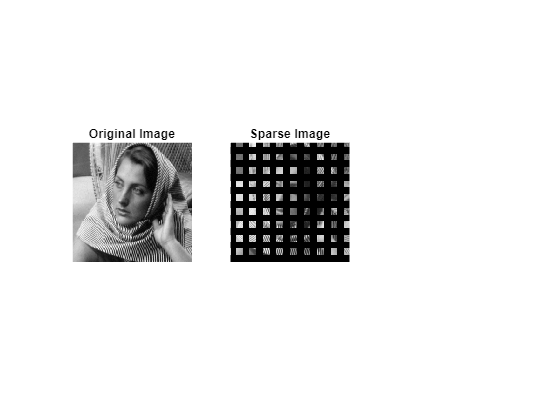

imageFile = 'mark_ruffalo17 (1).png';
originalImg = imread(imageFile);
originalImg = double(originalImg);
imshow(originalImg);

threshold = 20; % Error threshold for stopping
maxDepth = 12;   % Maximum recursion depth
filename = '1.dat'

filename = '1.dat'

homo_encode(originalImg, filename, threshold, maxDepth);

Extracted 16640 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to 1.dat_dict.mat


function homo_decode(filename, originalImg)
    % Homo_decode: Decodes an encoded file, reconstructs the sparse image,
    % performs homogeneous diffusion, and calculates the MSE error.
    %
    % Inputs:
    %   - filename: The file name of the encoded data (e.g., 'encoded_file_2.dat')
    %   - originalImg: The original image for comparison
    
    % Step 1: Decode the Huffman-encoded file
    [height, width, bct_decoded, intensity_decoded] = decode_huffman_file_v2(filename);
    global BCT;
    BCT = bct_decoded;
    
    % Step 2: Reconstruct the sparse image using the decoder function
    initial_region = [1, 1, height, width]; % Entire image region
    [decodedImage, decodedLocations] = decoder(initial_region, intensity_decoded);

    % Step 3: Perform Homogeneous Diffusion
    num_iterations = 100;  % Number of iterations
    lambda = 0.1;          % Diffusion rate
    mask = decodedImage > 0.1;  % Create mask for the sparse image

    % Perform diffusion
    reconsImage = homo_diffusion(decodedImage, mask, num_iterations, lambda);

    % Calculate MSE error
    mseError = mean((reconsImage(:) - originalImg(:)).^2);
    fprintf('Mean Squared Error (MSE): %.4f\n', mseError);

    % Step 4: Display the results
    figure;
    subplot(1, 3, 1); imshow(originalImg, []); title('Original Image');
    subplot(1, 3, 2); imshow(uint8(decodedImage), []); title('Sparse Image');
    subplot(1, 3, 3); imshow(reconsImage, []); title('Homogeneous Diffusion');
end

Mean Squared Error (MSE): 185.3656


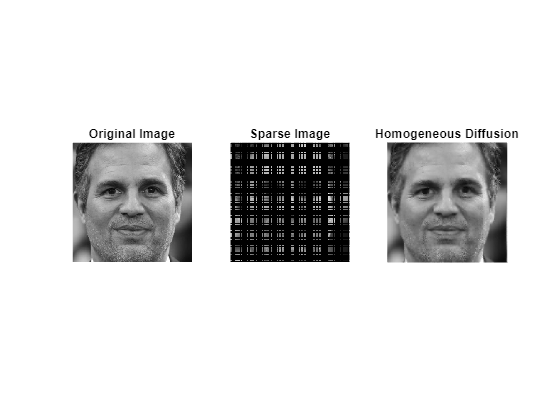

homo_decode(filename, originalImg);

function process_images(input_dir, output_dir, threshold, maxDepth)
    % Ensure the output directory exists
    if ~exist(output_dir, 'dir')
        mkdir(output_dir);
    end

    % Get a list of all files in the input directory
    image_files = dir(fullfile(input_dir, '*.png')); % Adjust '*.png' for your file type
    
    for k = 1:length(image_files)
        % Get the full path of the current image
        input_path = fullfile(image_files(k).folder, image_files(k).name);
        
        % Read the original image
        originalImg = imread(input_path);
        originalImg = double(originalImg);
        
        % Construct the output filename
        [~, name, ~] = fileparts(image_files(k).name); % Extract file name without extension
        output_filename = fullfile(output_dir, [name, '.dat']);
        
        % Call the homo_encode function
        homo_encode(originalImg, output_filename, threshold, maxDepth);
        fprintf('Encoded %s -> %s\n', image_files(k).name, output_filename);
        
        % Call the homo_decode function
        homo_decode(output_filename, originalImg);
    end
end

Extracted 14641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_1.dat_dict.mat
Encoded mark_1.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_1.dat
Mean Squared Error (MSE): 0.0000


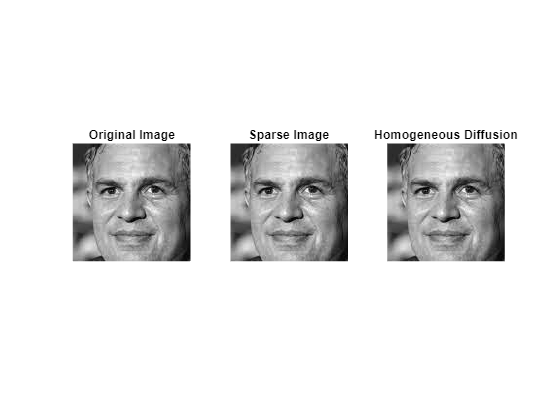

Extracted 16573 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_10.dat_dict.mat
Encoded mark_10.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_10.dat
       16575

       16641           2

       16576

       16641           2

       16577

       16641           2

       16578

       16641           2

       16579

       16641           2

       16580

       16641           2

       16581

       16641           2

       16582

       16641           2

       16583

       16641           2

       16584

       16641           2

       16585

       16641           2

       16586

       16641           2

       16587

       16641           2

       16588

       16641           2

       16589

       16641           2

       16590

       16641           2

       16591

       16641           2

       16592

    

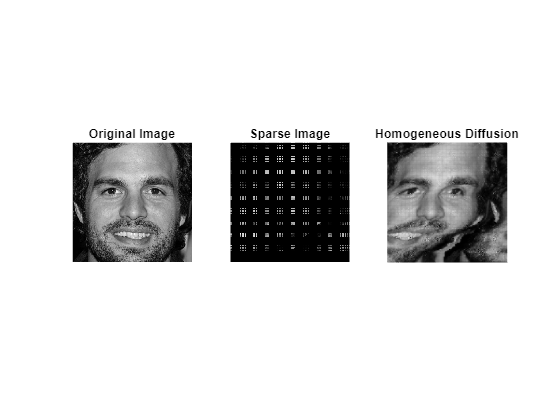

Extracted 15625 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_11.dat_dict.mat
Encoded mark_11.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_11.dat
Mean Squared Error (MSE): 0.0000


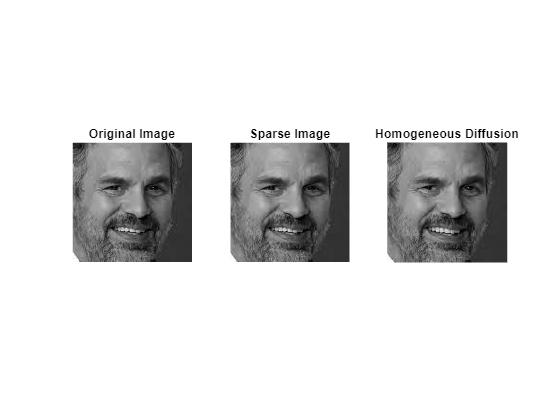

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_12.dat_dict.mat
Encoded mark_12.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_12.dat
Mean Squared Error (MSE): 156.9413


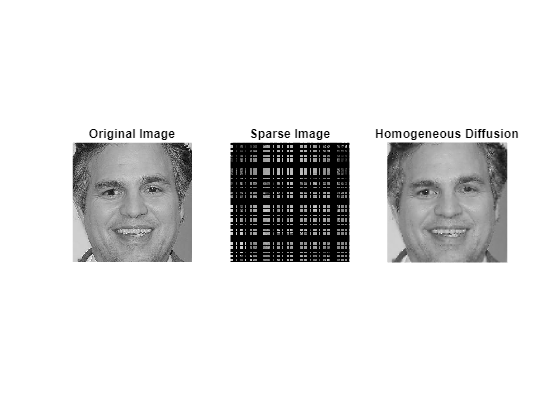

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_13.dat_dict.mat
Encoded mark_13.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_13.dat
Mean Squared Error (MSE): 2631.9325


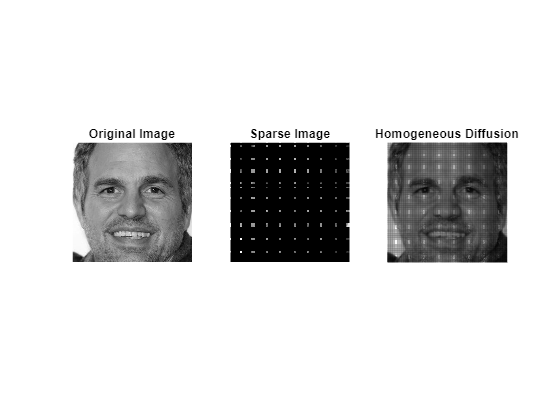

Extracted 16640 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_14.dat_dict.mat
Encoded mark_14.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_14.dat
Mean Squared Error (MSE): 154.6089


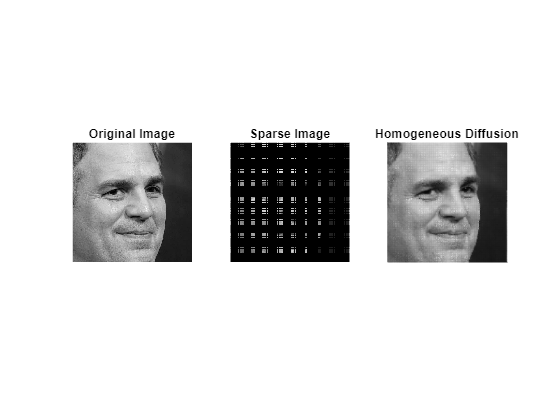

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_15.dat_dict.mat
Encoded mark_15.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_15.dat
Mean Squared Error (MSE): 61.0075


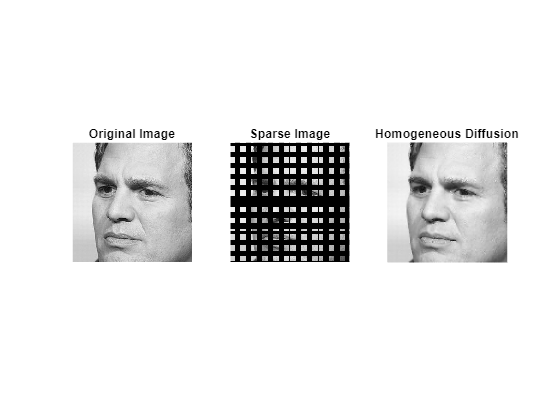

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_16.dat_dict.mat
Encoded mark_16.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_16.dat
Mean Squared Error (MSE): 7.4817


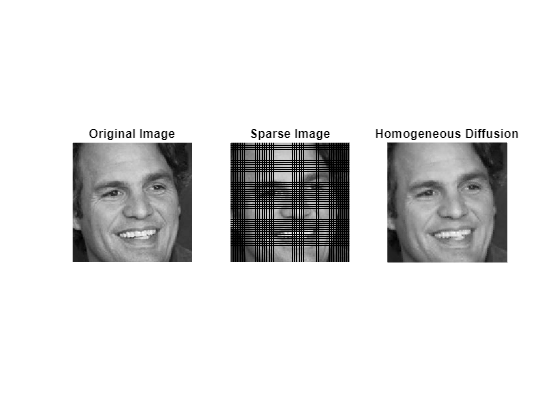

Extracted 16635 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_17.dat_dict.mat
Encoded mark_17.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_17.dat
       16636

       16641           2

       16637

       16641           2

       16638

       16641           2

       16639

       16641           2

       16640

       16641           2

       16641

       16641           2

Mean Squared Error (MSE): 4024.0277


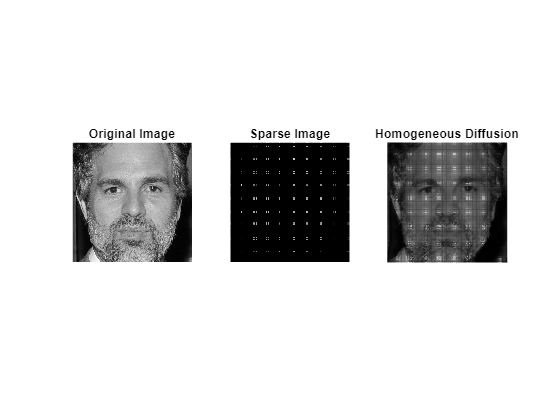

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_18.dat_dict.mat
Encoded mark_18.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_18.dat
Mean Squared Error (MSE): 58.9259


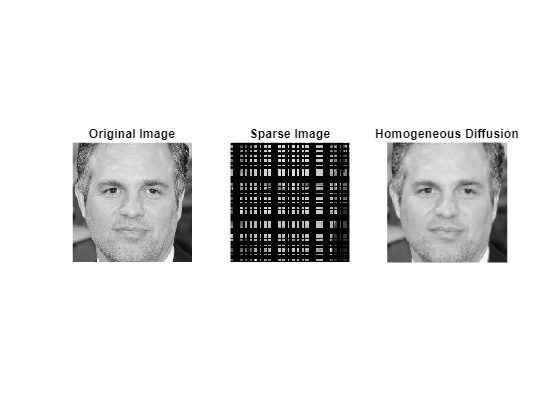

Extracted 16606 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_19.dat_dict.mat
Encoded mark_19.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_19.dat
       16607

       16641           2

       16608

       16641           2

       16609

       16641           2

       16610

       16641           2

       16611

       16641           2

       16612

       16641           2

       16613

       16641           2

       16614

       16641           2

       16615

       16641           2

       16616

       16641           2

       16617

       16641           2

       16618

       16641           2

       16619

       16641           2

       16620

       16641           2

       16621

       16641           2

       16622

       16641           2

       16623

       16641           2

       16624

    

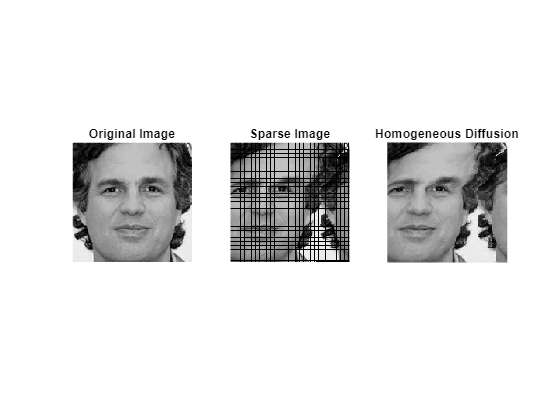

Extracted 13671 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_2.dat_dict.mat
Encoded mark_2.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_2.dat
       13672

       13907           2

       13673

       13907           2

       13674

       13907           2

       13675

       13907           2

       13676

       13907           2

       13677

       13907           2

       13678

       13907           2

       13679

       13907           2

       13680

       13907           2

       13681

       13907           2

       13682

       13907           2

       13683

       13907           2

       13684

       13907           2

       13685

       13907           2

       13686

       13907           2

       13687

       13907           2

       13688

       13907           2

       13689

       

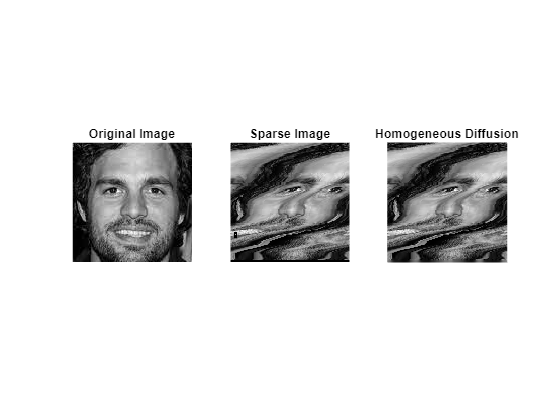

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_20.dat_dict.mat
Encoded mark_20.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_20.dat
Mean Squared Error (MSE): 21.4118


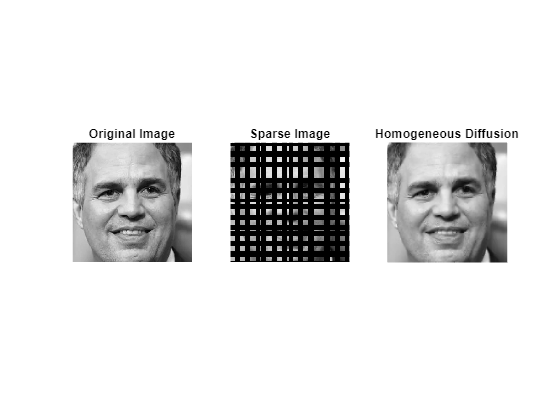

Extracted 12768 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_3.dat_dict.mat
Encoded mark_3.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_3.dat
Mean Squared Error (MSE): 322.5983


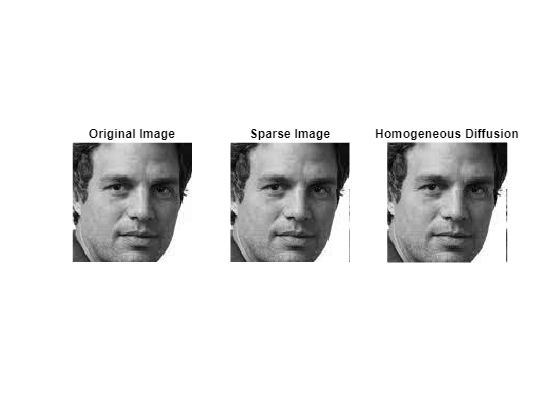

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_4.dat_dict.mat
Encoded mark_4.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_4.dat
Mean Squared Error (MSE): 39.5407


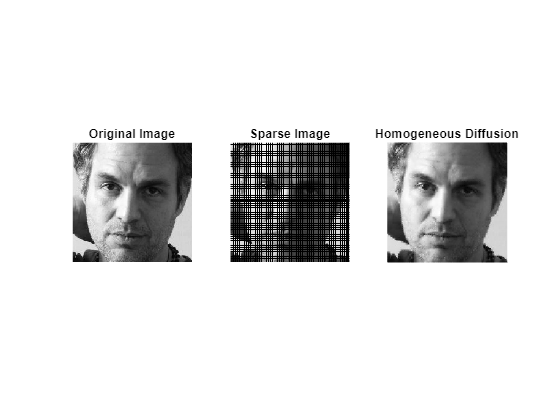

Extracted 16640 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_5.dat_dict.mat
Encoded mark_5.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_5.dat
Mean Squared Error (MSE): 185.3656


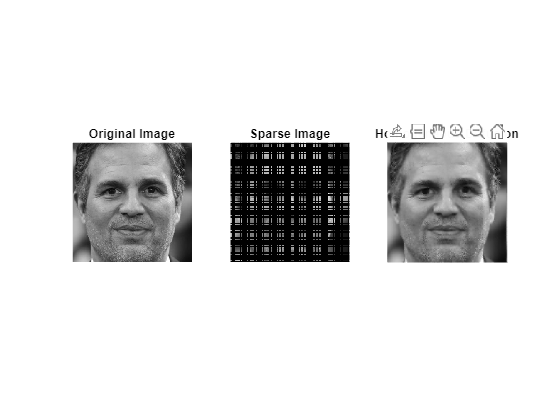

Extracted 16640 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_6.dat_dict.mat
Encoded mark_6.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_6.dat
Mean Squared Error (MSE): 4468.2598


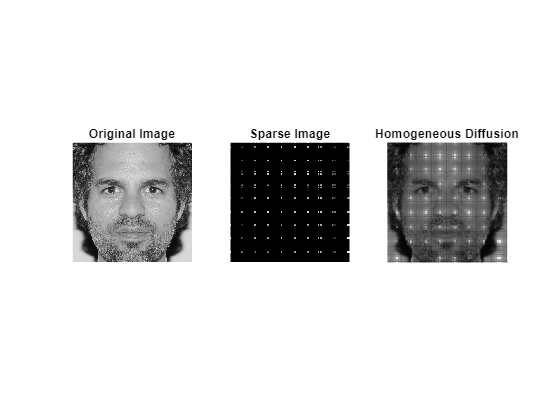

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_7.dat_dict.mat
Encoded mark_7.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_7.dat
Mean Squared Error (MSE): 23.8525


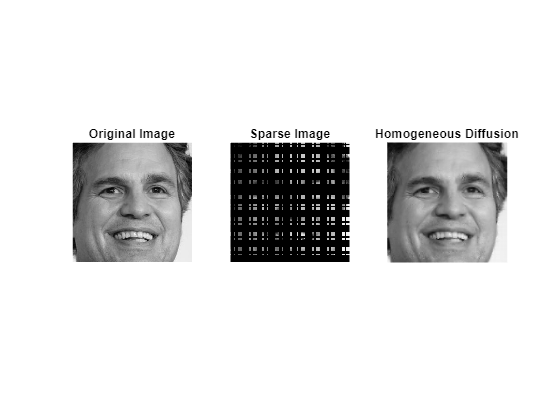

Extracted 16641 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_8.dat_dict.mat
Encoded mark_8.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_8.dat
Mean Squared Error (MSE): 37.0074


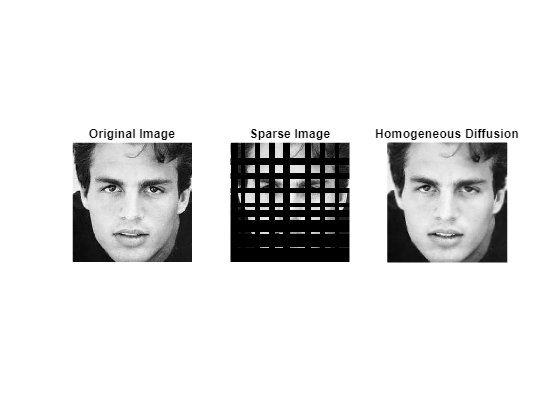

Extracted 16632 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.
Huffman dictionary saved to D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_9.dat_dict.mat
Encoded mark_9.png -> D:\iitb\Sem5\CS663-DIP\project\encoded_imgs\mark_9.dat
       16635

       16641           2

       16636

       16641           2

       16637

       16641           2

       16638

       16641           2

       16639

       16641           2

       16640

       16641           2

       16641

       16641           2

Mean Squared Error (MSE): 861.1005


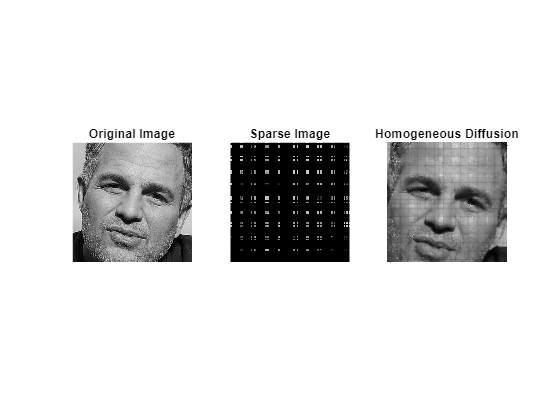

input_dir = 'D:\iitb\Sem5\CS663-DIP\project\imgs\bw';
output_dir = 'D:\iitb\Sem5\CS663-DIP\project\encoded_imgs';
threshold = 20;   % Example threshold
maxDepth = 12;     % Example maximum depth

process_images(input_dir, output_dir, threshold, maxDepth);

threshold = 20; % Error threshold for stopping
maxDepth = 12;   % Maximum recursion depth
filename = 'dct.dat'

filename = 'dct.dat'

img = imread('mark_14.png'); % Replace 'example.jpg' with your image   % Convert to grayscale if it's a color image
img_double = double(img); % Convert to double for processing


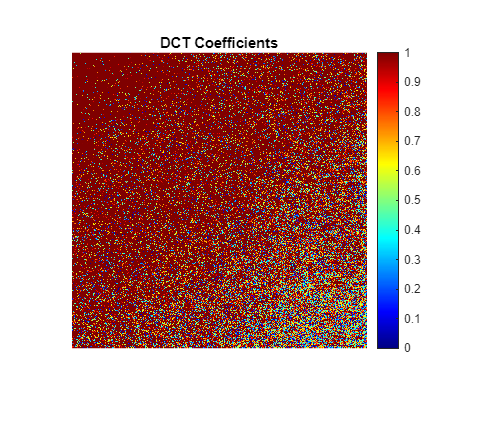

% Load an image and convert to grayscale
img = imread('mark_14.png'); % Replace 'example.jpg' with your image    % Convert to grayscale if it's a color image
img_double = double(img); % Convert to double for processing

% Display the original image
figure;
imshow(uint8(img_double));
title('Original Image');
% Display the original image
figure;
imshow(uint8(img_double));
title('Original Image');

% Perform DCT on the entire image
dct_coeffs = dct2(img_double);

% Display the DCT coefficients (log scale for better visualization)
figure;
dctimg = log(abs(dct_coeffs) + 1);
imshow(dctimg);
colormap(gca, jet); % Use color map for better visualization
colorbar;
title('DCT Coefficients');

homo_encode(filename, dctimg, 20, maxDepth);

Extracted 1 locations and vertex values from the sparse image.
Extracted 1 locations and vertex values from the sparse image.


Error using fopen
File identifier must be an integer-valued scalar of type double.

Error in homo>save_huffman_encoded_file_v2 (line 467)
    fid = fopen(filename, 'wb');

Error in homo>homo_encode (line 611)
    save_huffman_encoded_file_v2(filename, height, width, bct_size, bct, vertexValues);

homodecode(filname);

% Perform IDCT on the entire image
reconstructed_img = idct2(dct_coeffs);

% Display the reconstructed image
figure;
imshow(uint8(reconstructed_img));
title('Reconstructed Image After Quantization');



